# Reduce FIR Filter Delay

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and designs the absorption filter.

[whaley,fs] = audioread("./data/whalesound.wav");
n = numel(whaley);
fr = (0:n-1)*(fs/n);
fr = fr(1:n/2+1);
waterabs = absorption(fr);
f = fr/fs*2;
b = fir2(10,f,waterabs);

## Task 1

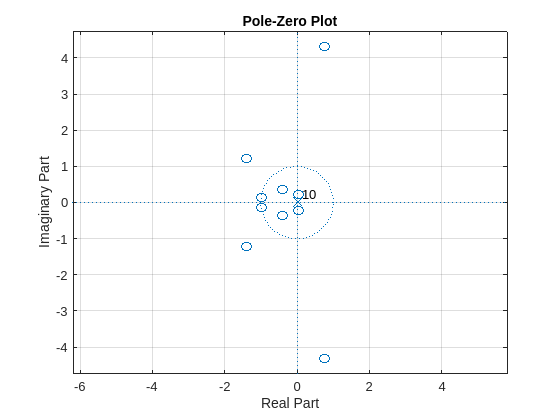

[z,p] = tf2zpk(b,1);
zplane(z,p)
grid on

## Task 2

bmin = polystab(b)

bmin =     0.0007    0.0022    0.0033    0.0027    0.0014    0.0005    0.0001    0.0000    0.0000    0.0000    0.0000


bmin = bmin * norm(b)/norm(bmin);

## Task 3 

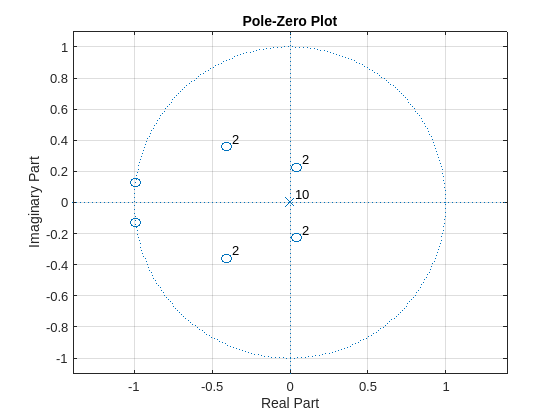

[z,p] = tf2zpk(bmin,1);
zplane(z,p)
grid on

## Task 4

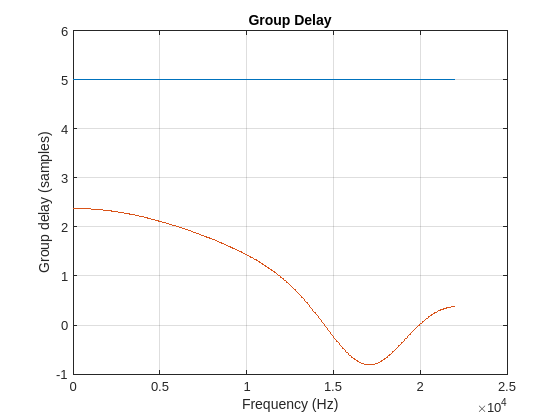

grpdelay(b,1,[],fs)
hold on
grpdelay(bmin,1,[],fs)
hold off

% Calculating the absorption coefficent of seawater in dB / km
% CWJ for AOR Sept 2010

function [alpha] = absorption(freq,km)
    % Following Kinsler, et al "Fundamentals of Acoustics, Fourth Edition" p. 226-228.
    pH = 8; % pH
    S = 35; % salinity in ppt
    T = 5; % temperature in C
    Z = 0; % depth in km
    if nargin == 1
        km = 20;
    end
    
    f_1 = 780*exp(T/29);
    f_2 = 42000*exp(T/18);
    A = 0.083*(S/35)*exp(T/31 - Z/91 + 1.8*(pH-8));
    B = 22*(S/35)*exp(T/14-Z/6);
    C = 4.9E-10*exp(-T/26 - Z/25);
    boric_acid = A./(f_1^2+freq.^2); % contribution from boric acid
    MgSO4 = B./(f_2^2+freq.^2); % contribution from MgSO4
    hydrostatic = C; % contribution from hydrostatic pressure
    alpha = (boric_acid + MgSO4 + hydrostatic).*freq.^2;
    alpha = 10.^(-alpha*km/20); % convert from dB to linear
end